The positions of the anatomical landmarks with respect to the segment frames are estimated using regression equations. For comparison, we compare the results of our OMC measurements with the scaling result of Xsens MVN (version 2021.2.0).

XsensStatic

RKneeJointPos =    82.0000    2.6000  429.9000


RAnkleJointPos =    53.1000    2.1000   70.7000


RKneeJointPos =    81.0000   -1.9000  457.4000


RAnkleJointPos =    50.3000   -2.5000   75.4000


RKneeJointPos =    80.1000   -6.4000  484.9000


RAnkleJointPos =    47.5000   -7.1000   80.0000


RKneeJointPos =    79.1000  -11.0000  512.5000


RAnkleJointPos =    44.6000  -11.6000   84.6000


RKneeJointPos =    78.1000  -15.5000  540.0000


RAnkleJointPos =    41.8000  -16.2000   89.2000


MarkTableXsens = 5×14 table
    SubjectID       REFMX        REFMY      REFMZ        REFLX        REFLY     REFLZ        RMMX         RMMY       RMMZ         RLMX         RLMY       RLMZ     Height(cm)
    _________    ___________    _______    _______    ___________    _______    ______    ___________    _______    _______    ___________    _______    ______    __________

        1         3.5527e-15    -370.84    -33.397     3.5527e-15    -371.23    33.397              0    -360.04    -28.851              0    -359.71    24.398       1500   
        2         7.1054e-15    -393.75    -35.446     7.1054e-15    -394.17    35.446     3.5527e-15    -382.96    -30.697     3.5527e-15    -382.61    25.947       1600   
        3        -3.5527e-15    -416.64    -37.499    -3.5527e-15    -417.08    37.499              0    -405.96    -32.507              0    -405.59    27.514       1700   
        4                  0     -439.5    -39.536              0    -439.97    39.536    -3.5527e-15

MarkTableXsens_G = 5×14 table
    SubjectID     REFMX      REFMY     REFMZ      REFLX      REFLY     REFLZ      RMMX       RMMY       RMMZ      RLMX       RLMY       RLMZ     Height(cm)
    _________    _______    _______    ______    _______    _______    ______    _______    _______    ______    _______    _______    ______    __________

        1        -24.046    -39.796    429.88    -24.046    -106.59    429.88    -46.874    -44.342    70.732    -46.874    -97.591    70.732       1500   
        2        -25.497    -42.396     457.4    -25.497    -113.29     457.4    -49.795    -47.145    75.392    -49.795    -103.79    75.392       1600   
        3        -26.983    -44.989    484.95    -26.983    -119.99    484.95    -52.691    -49.982    79.992    -52.691       -110    79.992       1700   
        4        -28.458    -47.579    512.52    -28.458    -126.65    512.52    -55.622     -52.81    84.698    -55.622    -116.19    84.698       1800   
        5         -29.92    -50.1

JointTableXsensArray_G = 5×14 table
    SubjectID    PelvisX    PelvisY    PelvisZ    RHipJointX    RHipJointY    RHipJointZ    RKneeJointX    RKneeJointY    RKneeJointZ    RAnkleJointX    RAnkleJointY    RAnkleJointZ    Height(cm)
    _________    _______    _______    _______    __________    __________    __________    ___________    ___________    ___________    ____________    ____________    ____________    __________

        1           0          0        799.9        0.4            -71          800.1        -24.046        -73.193        429.88         -46.874         -70.967          70.732          1500   
        2           0          0        850.4        0.4          -75.5          850.5        -25.497        -77.842         457.4         -49.795         -75.467          75.392          1600   
        3           0          0        900.9        0.4            -80          900.9        -26.983        -82.489        484.95         -52.691         -79.992          79.992 

Data preprocessing.

AoRandMarkerPosCalculation

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

ans = -9.6982

ans = -6.9747

ans = 0.3583

ans = -2.9746e-18

ans = 9.9342

ans = 11.2850

ans = 6.6774

ans = -3.4182

ans = -9.9494

ans = 0.1038

ans = 6.7334

ans = 7.1802

ans = 2.4766

we calculated the regression equations of anatomical landmark positions in femoral and tibia frames of all subjects based on OMC data.

LandmarkRegression

mRegressTable_Height = 12×6 table
               b0           b1         b2     RSqure       p-Value        SD  
             _______    ___________    __    _________    __________    ______

    REFMX          0              0    0           NaN           NaN         0
    REFMY    -11.949       -0.23211    0       0.24029      0.042426    21.465
    REFMZ    -51.859     0.00096682    0     0.0067331       0.81123    4.1089
    REFLX          0              0    0           NaN           NaN         0
    REFLY    -3.1015       -0.23789    0       0.23825      0.042834    22.088
    REFLZ     51.859    -0.00096682    0     0.0067331       0.81123    4.1089
    RMMX     -65.268       0.045241    0        0.1356       0.17903    6.1697
    RMMY      156.41       -0.31194    0       0.60325    0.00020311    13.099
    RMMZ     -37.062      0.0037473    0      0.017739       0.68626    3.6403
    RLMX      65.268      -0.045241    0        0.1356       0.17903    6.1697
    RLMY      125

mRegressTable_Height_ShankL = 2×6 table
              b0          b1           b2       RSqure      p-Value        SD  
            ______    __________    ________    _______    __________    ______

    RMMY    62.698      -0.08354    -0.76622    0.90017    5.3608e-08    6.5513
    RLMY    2.8297    -0.0017176    -0.99914    0.99406    3.3332e-17     1.648


mRegressTable_Height_ShankM = 2×6 table
              b0           b1            b2       RSqure      p-Value        SD  
            _______    ___________    ________    _______    __________    ______

    RMMY    -3.6414    -0.00095696    -0.98267    0.99417    2.4986e-17    1.5869
    RLMY    -31.098      0.0046158    -0.96214    0.87185    3.1301e-07    7.6771


mRegressTable_KneeW = 2×6 table
                b0           b1       b2    RSqure      p-Value         SD   
             _________    ________    __    _______    __________    ________

    REFMZ    -0.051663    -0.49921    0     0.99992    7.5556e-34    0.037459
    REFLZ     0.051663     0.49921    0     0.99992    7.5556e-34    0.037459


mRegressTable_Height_AnkleW = 4×6 table
              b0          b1           b2       RSqure     p-Value       SD  
            _______    _________    ________    _______    ________    ______

    RMMX    -67.707     0.053466    -0.17226    0.14356     0.34757    6.1411
    RMMZ    -44.878     0.031291    -0.58179     0.2791    0.091873    3.1173
    RLMX     67.707    -0.053466     0.17226    0.14356     0.34757    6.1411
    RLMZ     44.878    -0.031291     0.58179     0.2791    0.091873    3.1173


fRegressTable_Height = 12×6 table
               b0          b1        b2     RSqure      p-Value        SD  
             _______    _________    __    ________    __________    ______

    REFMX          0            0    0          NaN           NaN         0
    REFMY     568.01     -0.58419    0      0.82131    3.7705e-06    13.329
    REFMZ     49.089    -0.059936    0       0.3945      0.012324    3.6813
    REFLX          0            0    0          NaN           NaN         0
    REFLY     494.03     -0.53872    0      0.82548    3.9435e-06    12.105
    REFLZ    -49.089     0.059936    0       0.3945      0.012324    3.6813
    RMMX      27.017    -0.010697    0     0.026902       0.58362    3.9307
    RMMY      28.396     -0.23814    0      0.28816      0.041283    18.052
    RMMZ      13.842    -0.025786    0       0.2369      0.062481     2.287
    RLMX     -27.017     0.010697    0     0.026902       0.58362    3.9307
    RLMY      87.397     -0.28059    0       0.3373  

fRegressTable_Height_ShankL = 2×6 table
              b0          b1          b2       RSqure      p-Value        SD  
            _______    ________    ________    _______    __________    ______

    RMMY    -66.412    0.018946    -0.87419    0.88684    9.8926e-07    7.1789
    RLMY    -35.334    0.023792     -1.0074    0.99514    1.2042e-15    1.6011


fRegressTable_Height_ShankM = 2×6 table
              b0         b1           b2       RSqure      p-Value        SD  
            ______    _________    ________    _______    __________    ______

    RMMY    35.417     -0.02569    -0.98018    0.99496    1.7419e-15    1.5153
    RLMY    94.747    -0.073926     -0.9549    0.89607     4.721e-07    7.5697


fRegressTable_KneeW = 2×6 table
                b0          b1       b2    RSqure      p-Value         SD   
             ________    ________    __    _______    __________    ________

    REFMZ    -0.15172    -0.49806    0     0.99984    1.2307e-27    0.058491
    REFLZ     0.15172     0.49806    0     0.99984    1.2307e-27    0.058491


fRegressTable_Height_AnkleW = 4×6 table
              b0          b1          b2       RSqure      p-Value       SD  
            _______    _________    _______    _______    _________    ______

    RMMX     32.367    -0.029388     0.4091    0.32445      0.10836    3.2571
    RMMZ     9.6133    -0.011409     -0.313    0.63152    0.0023784    1.5767
    RLMX    -32.367     0.029388    -0.4091    0.32445      0.10836    3.2571
    RLMZ    -9.6133     0.011409      0.313    0.63152    0.0023784    1.5767


k = 9

aRegressTable_Height = 12×6 table
               b0          b1        b2    RSqure      p-Value        SD  
             _______    _________    __    _______    __________    ______

    REFMX          0            0    0         NaN           NaN         0
    REFMY     153.93     -0.32772    0     0.65418    1.1932e-08    20.247
    REFMZ      -17.9    -0.018494    0     0.12581      0.049594    4.1738
    REFLX          0            0    0         NaN           NaN         0
    REFLY     152.63      -0.3274    0     0.66945    6.0673e-09    19.536
    REFLZ       17.9     0.018494    0     0.12581      0.049594    4.1738
    RMMX     -38.215     0.029701    0     0.18192      0.016955    5.3859
    RMMY       65.58      -0.2606    0     0.66612    7.4714e-09    15.692
    RMMZ     -3.8983    -0.014988    0     0.14518      0.044736    3.1431
    RLMX      38.215    -0.029701    0     0.18192      0.016955    5.3859
    RLMY      58.975     -0.26245    0     0.63549    2.8001e-08 

aRegressTable_Height_ShankL = 2×6 table
              b0          b1           b2       RSqure      p-Value        SD  
            _______    _________    ________    _______    __________    ______

    RMMY     18.408    -0.043019    -0.83231    0.92823    1.0555e-10    7.1051
    RLMY    -1.6236    0.0014699     -1.0013    0.99561      1.69e-18    1.7946


aRegressTable_Height_ShankM = 2×6 table
              b0           b1           b2       RSqure      p-Value        SD  
            _______    __________    ________    _______    __________    ______

    RMMY     1.3303    -0.0054559    -0.97591      0.996     1.956e-37    1.7168
    RLMY    -2.6147     -0.017696    -0.93626    0.92053    2.5186e-17    7.8789


aRegressTable_KneeW = 2×6 table
                b0           b1       b2    RSqure      p-Value        SD   
             _________    ________    __    _______    _________    ________

    REFMZ    -0.090074    -0.49877    0     0.99988    1.199e-63    0.048739
    REFLZ     0.090074     0.49877    0     0.99988    1.199e-63    0.048739


aRegressTable_Height_AnkleW = 4×6 table
              b0           b1           b2       RSqure      p-Value       SD  
            _______    __________    ________    _______    _________    ______

    RMMX    -29.583      0.014583     0.25859    0.21922     0.026814    5.2635
    RMMZ    -16.966     0.0080364    -0.39517    0.39425    0.0007757    2.6444
    RLMX     29.583     -0.014583    -0.25859    0.21922     0.026814    5.2635
    RLMZ     16.966    -0.0080364     0.39517    0.39425    0.0007757    2.6444


my =     1.4160   11.0820   20.7479
   -0.2242   11.3039   22.8321
    2.9673   11.5852   20.2031
    3.0997   12.2031   21.3064
    1.5386   11.3415   21.1445
   10.3824   13.0009   15.6194
    1.7764   10.9514   20.1263
    0.2945   11.8806   23.4667
    0.8521   10.8163   20.7804
    3.8297   12.2488   20.6678


mErrorTable = 4×3 table
                  X                Y                 Z      
            _____________    ______________    _____________

    REFM    {'0.0±0.0'  }    {'-9.9±21.5' }    {'11.4±4.3' }
    REFL    {'0.0±0.0'  }    {'-9.0±22.1' }    {'-11.4±4.3'}
    RMM     {'-14.3±6.6'}    {'-27.2±13.8'}    {'-3.1±3.9' }
    RLM     {'14.3±6.6' }    {'-17.3±15.4'}    {'-2.0±3.8' }


fErrorTable = 4×3 table
                 X                Y                 Z      
            ____________    ______________    _____________

    REFM    {'0.0±0.0' }    {'-18.6±22.2'}    {'12.3±4.2' }
    REFL    {'0.0±0.0' }    {'-18.8±19.6'}    {'-12.3±4.2'}
    RMM     {'-9.6±4.0'}    {'-30.2±18.4'}    {'-3.1±2.3' }
    RLM     {'9.6±4.0' }    {'-19.9±19.4'}    {'-1.7±2.3' }


aErrorTable = 4×3 table
                  X                Y                 Z      
            _____________    ______________    _____________

    REFM    {'0.0±0.0'  }    {'-14.0±22.0'}    {'11.9±4.2' }
    REFL    {'0.0±0.0'  }    {'-13.7±21.3'}    {'-11.9±4.2'}
    RMM     {'-12.1±6.0'}    {'-28.6±16.0'}    {'-3.1±3.2' }
    RLM     {'12.1±6.0' }    {'-18.5±17.2'}    {'-1.9±3.2' }


CopyToWord = 60×6 cell 数组
    {'-11.949'}    {'-0.232'}    {'0.000' }    {'0.240'}    {'0.042'}    {'-0.0±23.3'}
    {'-51.859'}    {'0.001' }    {'0.000' }    {'0.007'}    {'0.811'}    {'-0.1±4.6' }
    {'-3.102' }    {'-0.238'}    {'0.000' }    {'0.238'}    {'0.043'}    {'0.1±24.0' }
    {'51.859' }    {'-0.001'}    {'0.000' }    {'0.007'}    {'0.811'}    {'0.1±4.6'  }
    {'-65.268'}    {'0.045' }    {'0.000' }    {'0.136'}    {'0.179'}    {'0.0±7.1'  }
    {'156.409'}    {'-0.312'}    {'0.000' }    {'0.603'}    {'0.000'}    {'0.2±15.0' }
    {'-37.062'}    {'0.004' }    {'0.000' }    {'0.018'}    {'0.686'}    {'0.0±4.4'  }
    {'65.268' }    {'-0.045'}    {'0.000' }    {'0.136'}    {'0.179'}    {'-0.0±7.1' }
    {'125.652'}    {'-0.300'}    {'0.000' }    {'0.521'}    {'0.001'}    {'0.3±17.3' }
    {'37.062' }    {'-0.004'}    {'0.000' }    {'0.018'}    {'0.686'}    {'-0.0±4.4' }
    {'62.698' }    {'-0.084'}    {'-0.766'}    {'0.900'}    {'0.000'}    {'-0.4±7.9' }
    {'2.830'  }  

CopyToWordXsens = 12×3 cell 数组
    {'0.0±0.0'  }    {'-9.9±21.5' }    {'11.4±4.3' }
    {'0.0±0.0'  }    {'-9.0±22.1' }    {'-11.4±4.3'}
    {'-14.3±6.6'}    {'-27.2±13.8'}    {'-3.1±3.9' }
    {'14.3±6.6' }    {'-17.3±15.4'}    {'-2.0±3.8' }
    {'0.0±0.0'  }    {'-18.6±22.2'}    {'12.3±4.2' }
    {'0.0±0.0'  }    {'-18.8±19.6'}    {'-12.3±4.2'}
    {'-9.6±4.0' }    {'-30.2±18.4'}    {'-3.1±2.3' }
    {'9.6±4.0'  }    {'-19.9±19.4'}    {'-1.7±2.3' }
    {'0.0±0.0'  }    {'-14.0±22.0'}    {'11.9±4.2' }
    {'0.0±0.0'  }    {'-13.7±21.3'}    {'-11.9±4.2'}
    {'-12.1±6.0'}    {'-28.6±16.0'}    {'-3.1±3.2' }
    {'12.1±6.0' }    {'-18.5±17.2'}    {'-1.9±3.2' }


ans = 1

ans = 2

j = 13

b0 = -3.6414

b1 = -9.5696e-04

b2 = -0.9827

b0 = -31.0977

b1 = 0.0046

b2 = -0.9621

ans = 1

ans = 2

j = 13

b0 = 35.4175

b1 = -0.0257

b2 = -0.9802

b0 = 94.7474

b1 = -0.0739

b2 = -0.9549

regMarkTableM = 20×13 table
    SubjectID    REFMX     REFMY      REFMZ     REFLX     REFLY     REFLZ      RMMX      RMMY       RMMZ       RLMX       RLMY       RLMZ 
    _________    _____    _______    _______    _____    _______    ______    ______    _______    _______    _______    _______    ______

        1          0      -415.82    -44.229      0      -417.03    44.229    13.695     -368.9    -29.706    -13.695    -379.06    29.706
        2          0      -406.53     -46.57      0      -407.52     46.57    12.641    -377.07    -27.293    -12.641    -387.29    27.293
        4          0      -418.14    -48.506      0      -419.41    48.506    12.995     -404.4    -33.561    -12.995    -413.77    33.561
        5          0      -439.03    -53.543      0      -440.82    53.543    17.447    -441.86    -31.963    -17.447    -449.94    31.963
        6          0       -425.1    -49.863      0      -426.55    49.863    14.777    -409.18    -32.024    -14.777    -418.29    32.02

regMarkTableF = 18×13 table
    SubjectID    REFMX     REFMY      REFMZ     REFLX     REFLY     REFLZ      RMMX      RMMY       RMMZ       RLMX       RLMY       RLMZ 
    _________    _____    _______    _______    _____    _______    ______    ______    _______    _______    _______    _______    ______

        3          0      -337.48    -45.371      0      -340.99    45.371    11.168     -347.2    -26.703    -11.168    -353.79    26.703
        8          0      -454.32    -55.689      0      -448.73    55.689     6.903    -377.82    -30.218     -6.903     -393.4    30.218
        9          0      -407.59    -43.495      0      -405.64    43.495    9.2934     -389.1    -29.336    -9.2934    -400.48    29.336
       10          0      -355.01    -42.444      0      -357.15    42.444    9.9503    -373.66    -26.788    -9.9503    -381.04    26.788
       11          0      -366.69    -48.218      0      -367.93    48.218    6.4102    -362.63    -24.757    -6.4102    -371.27    24.75

IMC data processing for each subject: using the average knee AoR and the regression equations, we corrected the segment orientations measured by IMC. We calculated the anatomical landmark positions in the femoral and tibia frames. We then calculated the anatomical landmark trajectories for each subject. For verification, it is necessary to unify the global reference frame of IMC and OMC systems. Then we can obtain the trajectory errors.

TrajectoriesCalculation

MMeanAorF =    -0.1212   -0.1686    0.9782


MMeanAorT =    -0.0000    0.0056    1.0000


FMeanAorF =    -0.1722   -0.0574    0.9834


FMeanAorT =    -0.0000    0.0018    1.0000


i = 1

Average AoR correction


i = 2

Average AoR correction


i = 3

Average AoR correction


i = 4

i = 5

i = 6

Average AoR correction


i = 7

Average AoR correction


i = 8

i = 9

Average AoR correction


i = 10

Average AoR correction


i = 11

Average AoR correction


i = 12

Average AoR correction


i = 13

Average AoR correction


i = 14

Average AoR correction


i = 15

Average AoR correction


i = 16

Average AoR correction


i = 17

Average AoR correction


i = 18

Average AoR correction


i = 19

Average AoR correction


RMSTable = 3×4 table
                  REFM            REFL             RMM              RLM     
              ____________    ____________    _____________    _____________

    Male      {'26.5±6.3'}    {'23.4±7.4'}    {'53.3±10.5'}    {'55.1±13.0'}
    Female    {'32.6±9.1'}    {'31.9±9.6'}    {'57.3±27.5'}    {'56.0±27.4'}
    Total     {'30.4±8.5'}    {'28.7±9.5'}    {'55.8±22.2'}    {'55.7±22.5'}


RMSPercentTableM = 1×4 table
       REFM           REFL            RMM            RLM    
    ___________    ___________    ___________    ___________

    {'3.3±0.8'}    {'2.9±0.9'}    {'6.6±1.2'}    {'6.8±1.4'}


RMSPercentTableF = 1×4 table
       REFM           REFL            RMM            RLM    
    ___________    ___________    ___________    ___________

    {'4.4±1.1'}    {'4.3±1.2'}    {'7.6±3.6'}    {'7.5±3.6'}


EulErrorM =     4.1915    3.4073    8.0610    6.8256    3.2572    7.5553


EulErrorF =     4.4525    4.3419    7.0259    5.6249    4.4183    7.4212


ans = 156.6047

ans = 86.9275

AngleErrorM =     2.5639    6.9578


ans =     1.0478    1.8375


AngleErrorF =     4.1473    6.7963


ans =     1.4558    3.6030


MeanRMSAnglePercentM =     1.5965    7.3795


ans =     0.7058    2.0486


MeanRMSAnglePercentF =     2.4615    7.6086


ans =     0.8886    4.3950


rTable = 1×12 cell 数组
    {'0.999±0.001'}    {'0.817±0.196'}    {'0.999±0.002'}    {'0.999±0.001'}    {'0.824±0.198'}    {'0.999±0.001'}    {'0.999±0.000'}    {'0.727±0.302'}    {'0.961±0.087'}    {'0.999±0.001'}    {'0.723±0.299'}    {'0.967±0.055'}


CorrX =     0.9991    0.9992


CorrY =     0.7233    0.8237


CorrZ =     0.9609    0.9986


ICCX =     0.9992    0.9991    0.9992    0.9992


ICCY =     0.8170    0.8237    0.7274    0.7233


ICCZ =     0.9986    0.9986    0.9609    0.9672


ans = 0.9992

ans = 0.7728

ans = 0.9813

RegCorr

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

ans = 1.0000

ans = 1.0000

ans = 0.9670

ans = 0.9695

AoRCorr

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

ans = 0.9779

ans = 0.9777

ans = 0.9327

ans = 0.9317

Xsens validation.

i = 1

i = 2

i = 3

i = 4

i = 1

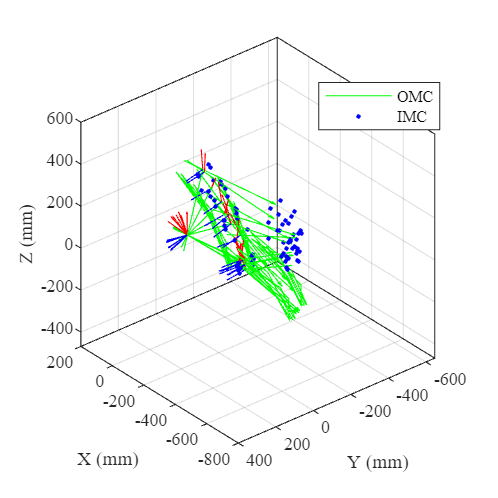

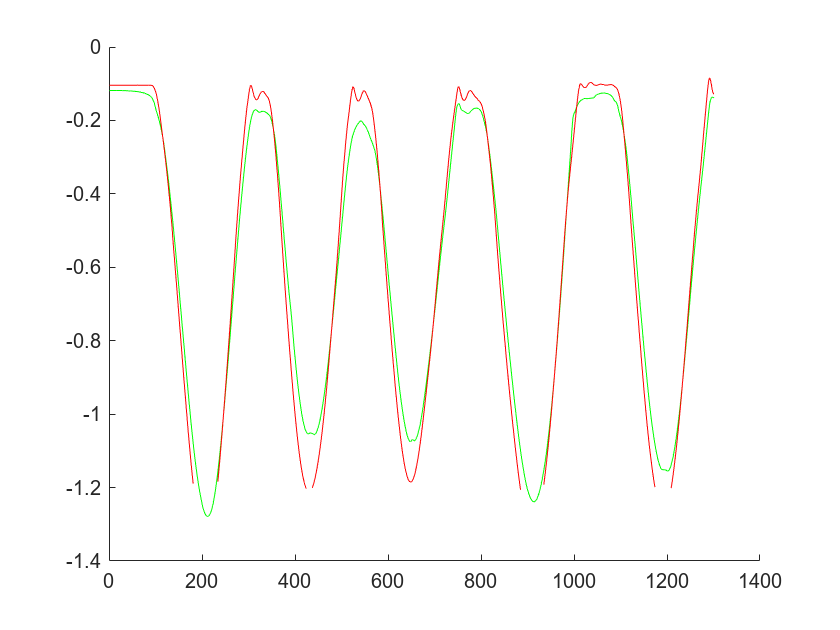

ROMF = 99.2241

ROMT = 93.9868

i = 2

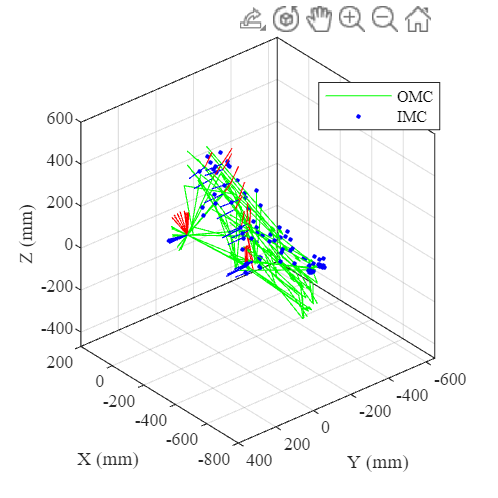

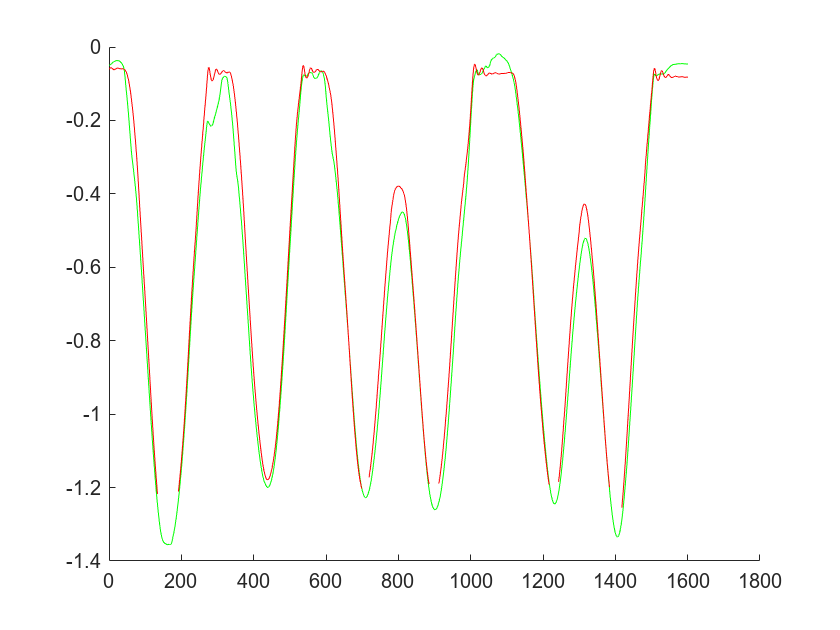

ROMF = 114.6418

ROMT = 114.8317

i = 3

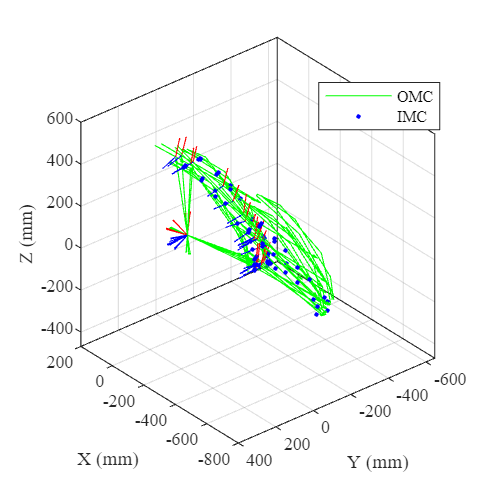

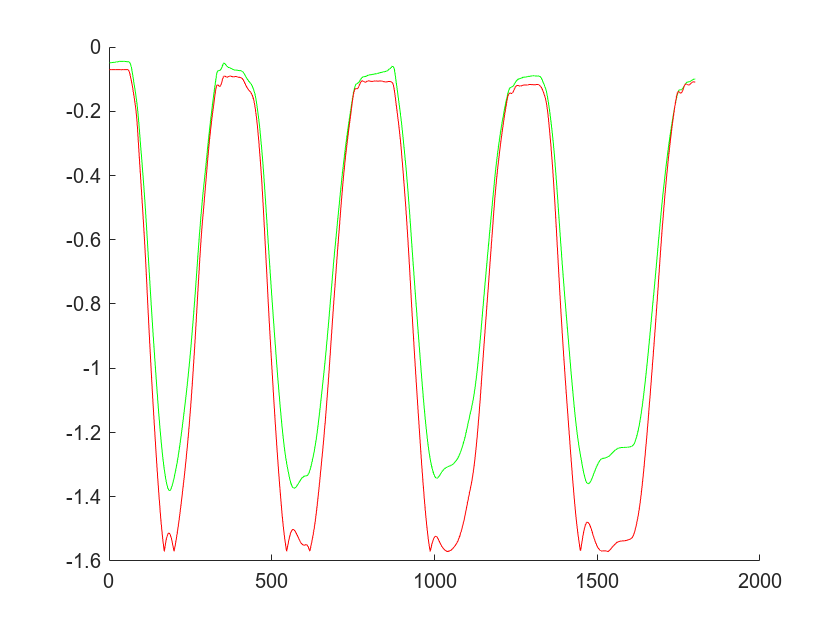

ROMF = 102.0753

ROMT = 95.1269

i = 4

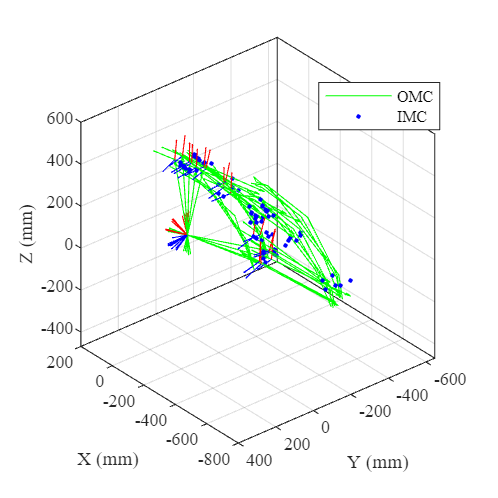

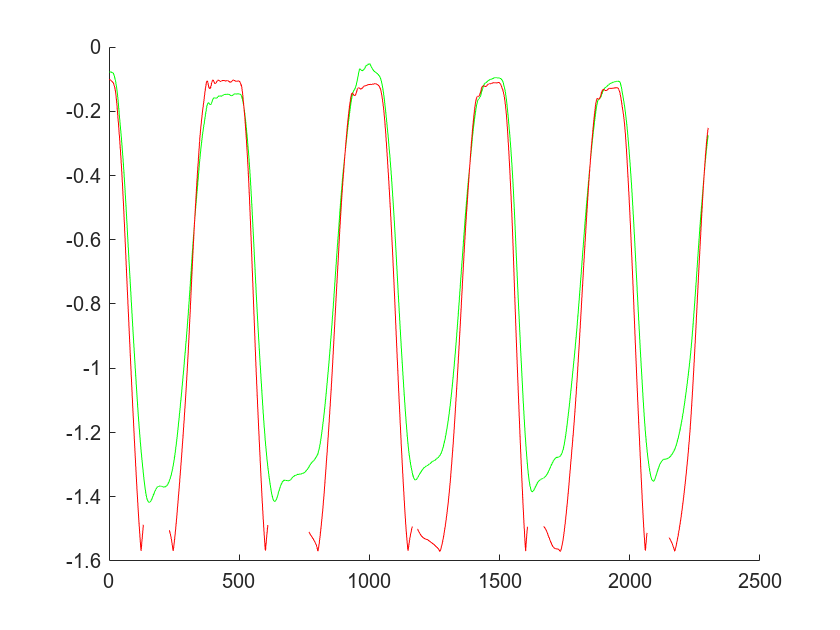

ROMF = 101.4610

ROMT = 93.4459

RMSTable = 4×4 table
     REFM      REFL      RMM       RLM  
    ______    ______    ______    ______

    46.548    62.362    248.75    267.72
    43.923    61.364    126.73     145.1
        78    56.457    136.15    119.17
    86.299    69.465    145.33    133.18


RMSEulTable = 4×6 table
    R UpperLeg Z    R UpperLeg Y    R UpperLeg X    R LowerLeg Z    R LowerLeg Y    R LowerLeg X
    ____________    ____________    ____________    ____________    ____________    ____________

        4.535          17.031          12.127          36.645           5.731          3.0592   
       4.1544          5.6965          5.8803          17.179          7.8971          2.1234   
       11.074          9.8028          13.794          5.7728          6.3644          12.747   
       12.202          13.624          14.608          3.0663          9.5575          12.941   


yAxisRMSEul =     4.8661   36.1538
    5.5947   17.1905
    8.8573   13.5468
   10.1514   13.4635


ans =     8.8330    8.1032


ans =     4.9042   38.4669
    4.8801   14.9702
    8.6773   14.2407
   10.0052   14.4078



XsensValidation